addpath("backend/")

image = im2double(imread("images/puzzle/pieces_clean.png"));
gaussFactor = 2

gaussFactor = 2

smallAreaPx = 1000

smallAreaPx = 1000

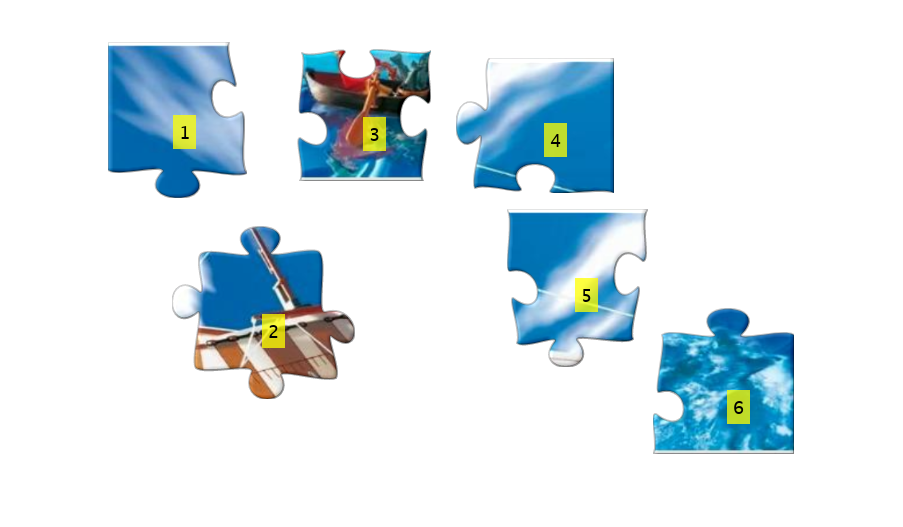


mask = image;
%
% imshow(mask)
mask = edge(rgb2gray(mask), 'canny');
%imshow(pieces, [])
mask = imgaussfilt(double(mask), gaussFactor);
%imshow(pieces, [])
mask = imbinarize(mask, "adaptive", "Sensitivity", 1.0);
%imshow(pieces, [])
mask = imcomplement(imfill(mask,[1 1]) - mask);
%imshow(pieces, [])
mask = bwareaopen(mask, smallAreaPx);
%imshow(pieces, [])
[mask,n] = bwlabel(mask);


%imshow(label2rgb(mask))

label = 1;
labeled = image;
while label <= n
    labeled = insertText(labeled, ...
        regionprops(mask==label,'Centroid').Centroid, ...
        label, ...
        "FontSize",18,"BoxOpacity",.75);
    label = label + 1;
end
imshow(labeled)

targetB = im2double(imread("images/puzzle/pirate_puzzle.jpg"));
target = rgb2gray(targetB);

figure;
hold on;

label = 1;
while label <= n
    reference = image .* (mask==label);
    reference = rgb2gray(reference);
    
    referencePoints = encodedFeatures("SURF", reference);
    targetPoints = encodedFeatures("SURF", target);
    [matchedReferencePoints, matchedTargetPoints] = matchingPoints( ...
        reference, referencePoints, ...
        target, targetPoints);
    
    if((matchedTargetPoints.length > 2) && (matchedReferencePoints.length > 2))
        [tform, estimatedReferencePoints, estimatedTargetPoints] = ...
            estimateGeometricTransform(matchedReferencePoints, matchedTargetPoints, 'affine');
        p = regionprops(mask==label,'all');
        targetB = insertText(targetB, ...
            transformPointsForward(tform,p.Centroid), ...
            label, ...
            "FontSize",18,"BoxOpacity",.85);
    else
        disp("No match found for " +  label + ".")
    end 
    
    label = label + 1;
end

No match found for 1.
No match found for 4.


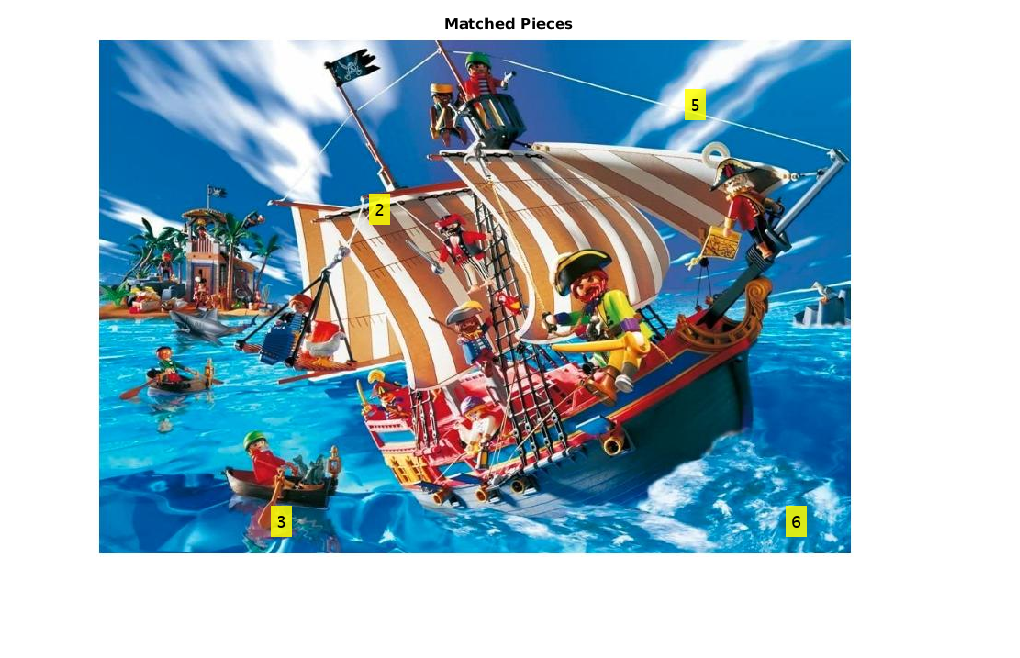


imshow(targetB);
title('Matched Pieces');
hold off;